## This script generates a color gradient from a given jpeg image

filepath="test-data/color_test.jpeg"

filepath = "test-data/color_test.jpeg"


% read i the image as an matrix of RGB values
reference_image=im2single(imread(filepath))

reference_image = 1800×2880×3 single array
reference_image(:,:,1) =

  Columns 1 through 999

    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.3412    0.

Then show the Image as a reference

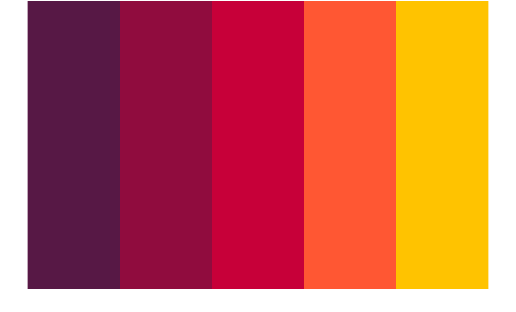

imshow(reference_image)

Next we need to isolate the `RGB` values from the matrix `reference_image` using the transformation $T_A =R^5 \to R^3$ for the   `R, G and B where`


$$T_{A_R } \to A=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack ,T_{A_G } \to A=\left\lbrack \begin{array}{c}
0\\
1\\
0
\end{array}\right\rbrack ,T_{A_B } \to A=\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$$


% get pixel height, width and rgb size from image
[px_h,px_w,dim]=size(reference_image)

px_h = 1800

px_w = 2880

dim = 3


% pre-allocate red, green and blue magnitude matricies
red_values=zeros(px_h,px_w)

red_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

green_values=zeros(px_h,px_w)

green_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

blue_values=zeros(px_h,px_w)

blue_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     


% declare transformations
Ar=[1 0 0];
Ag=[0 1 0];
Ab=[0 0 1];

for j=1:px_w
    for i=1:px_h
        rgb=[reference_image(i,j,1) reference_image(i,j,2) reference_image(i,j,3)];
        red=dot(rgb',Ar);
        green=dot(rgb',Ag);
        blue=dot(rgb',Ab)
        red_values(i,j)=red;
        green_values(i,j)=green;
        blue_values(i,j)=blue;
    end
end

Index in position 1 exceeds array bounds. Index must not exceed 1800.

Once we have the matrix for the red, green and blue values of each pixel, the we can create 3D least squares estimation